# Part 6: Simulation

## Exercise 6.1: Navigating a 2D maze

When the simulation environment is up-and-running, you should be able to see a drone flying through a maze from one end to the other. The waypoints are containted in the variable route, and the corresponding scaling and offset are 1 m and 0 m (respectively).  

**Task: ***Recompute route using the code from exercise 4.1 to navigate from points (0, 0, 1) to (3, 5, 1)  *

clc; clear all; close all;
addpath('maze');
addpath('maze\exercise_4_files\')
% First we get the map
run("maze\maze_1.m");

% Secondly we wish to define the start and end
% Define the starting and end position
boundry = 1;
start = [0, 0];
end_ = [3, 5];

% Run the algorithm to optain the route
plot_map(map, 1, boundry)
plot_start_stop(start, end_, 1)
route = flip(greedy_2d(flip(map), start+1, flip(end_+1)), 2);

Let's draw the map:

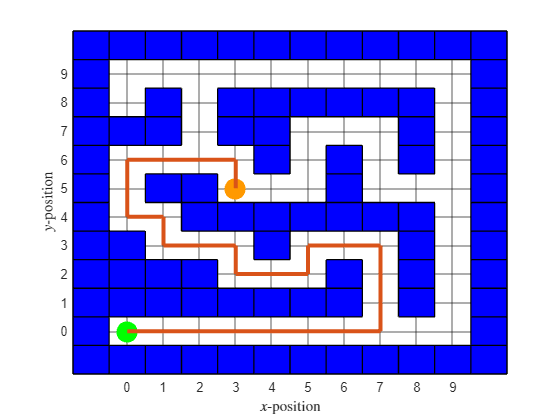

% Draw the map
% Draw a figure to show the map and process
plot_route(route, 1)
ylabel('$y$-position','Interpreter','Latex')
xlabel('$x$-position','Interpreter','Latex')

savepdf(figure(1), 'images/exe6_1_XY-plot')

## Exercise 6.2: Position Controller

Let's first get the model parameters needed;

run("model_params.m");

The simulation can be run by doing:

rho = [500; 0; 500; 0]; % angular velocity of the four propellers
SimData = sim('UAV_model.slx', 1);

Show figure;

figure(2);
plot3(SimData.p_out.signals.values(:,1), SimData.p_out.signals.values(:,2), SimData.p_out.signals.values(:,3));
title('Position of the CoG of the UAV');

#### Simulation Plot:

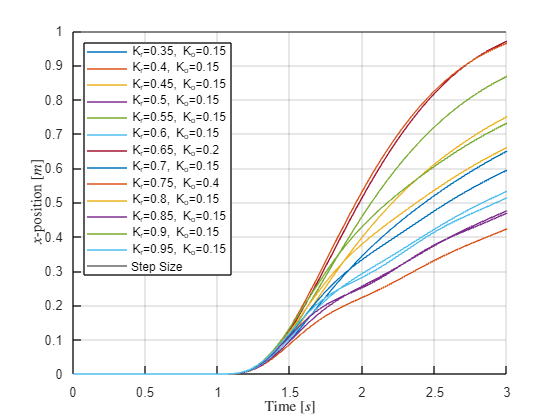

load("data/6_2_sims.mat")
close all;
for j = 5:17
    for i = 1+j*19:19+j*19
        if max(sims(i).pos.signals.values(1,:)) <= 1
            figure(1)
            hold on
            plot(sims(i).pos.time, sims(i).pos.signals.values(1,:),'DisplayName', strcat('K_r=',num2str((j)*0.05+0.1), ', K_o=', num2str((i-j*19)*0.05+0.1)))
            break
        end
    end
end
yline(1,'-','DisplayName', 'Step Size')
ylim([0, 1])
grid on 
legend(Location="northwest")
hold off
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('$x$-position $[m]$','Interpreter','Latex')
savepdf(figure(1), 'images/exe6_2_sim')

#### Testing the values at 1, 3 and 9 meters

## Exercise 6.3: Attitude Controller

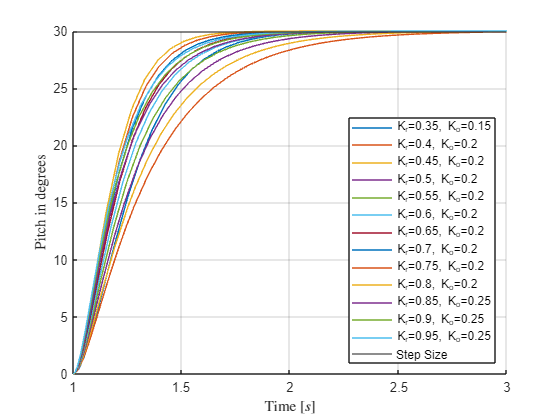

load("data/6_3_sims2.mat")
close all;
for j = 5:17
    for i = 1+j*19:19+j*19
        if max(sims(i).ang.signals.values(:,2)) <= pi/6
            figure(1)
            hold on
            plot(sims(i).ang.time, (180/pi)*sims(i).ang.signals.values(:,2),'DisplayName', strcat('K_r=',num2str((j)*0.05+0.1), ', K_o=', num2str((i-j*19)*0.05+0.1)))
            break
        end
    end
end
yline((180/pi)*pi/6,'-','DisplayName', 'Step Size')
ylim([0, 30])
xlim([1, 3])
legend(Location="southeast")
grid on
hold off
xlabel('Time $[s]$','Interpreter','Latex')
ylabel('Pitch in degrees','Interpreter','Latex')
savepdf(figure(1), 'images/exe6_3_sim')

## Exercise 6.4: Trajectory

% Initialization
close all
clear
clc

Run the trajectory generation:

% Trajectory generation

knots = [0 5];
waypoints = cell(1,2);
waypoints{1} = [0 ; 0 ; 1];
waypoints{2} = [9 ; 9 ; 1];
% We fixed
order = 7;
corridors.times = [1 2 3 4 5];
corridors.x_lower = [-1 3 8.75 8.5 8];
corridors.x_upper = [1 7 10.75 9.5 10];
corridors.y_lower = [-1 0 -0.5 3 8];
corridors.y_upper = [1 1 1.5 6 10];
corridors.z_lower = [0 0 0 0 0];
corridors.z_upper = [2 2 2 2 2];
% ...until here
make_plots = true;

poly_traj = uas_minimum_snap(knots, order, waypoints, corridors, make_plots);

function savepdf(figure, name)
    set(figure,'Units','Inches');
    pos = get(figure,'Position');
    set(figure,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])
    print(figure, name,'-dpdf','-r0')
end